% openExample('simulink_general/penddemoExample')

% cart --> (u[1]/m - g*sin(u[3])*cos(u[3]) + l*power(u[2],2)*sin(u[3]))/(Mcart/m + power(sin(u[3]),2))
% pend --> (-u[1]*cos(u[3])/m + (Mcart+m)*g*sin(u[3])/m - l*power(u[2],2)*sin(u[3])*cos(u[3]))/(l*(Mcart/m + power(sin(u[3]),2)))

% Initialize the Fuzzy Inference System with no rules
FIS = mamfis( ...
    'NumInputs', 2, ...
    'NumInputMFs', 2, ...
    'NumOutputs', 1, ...
    'NumOutputMFs', 4, ...
    'AddRule', 'none'...
    );

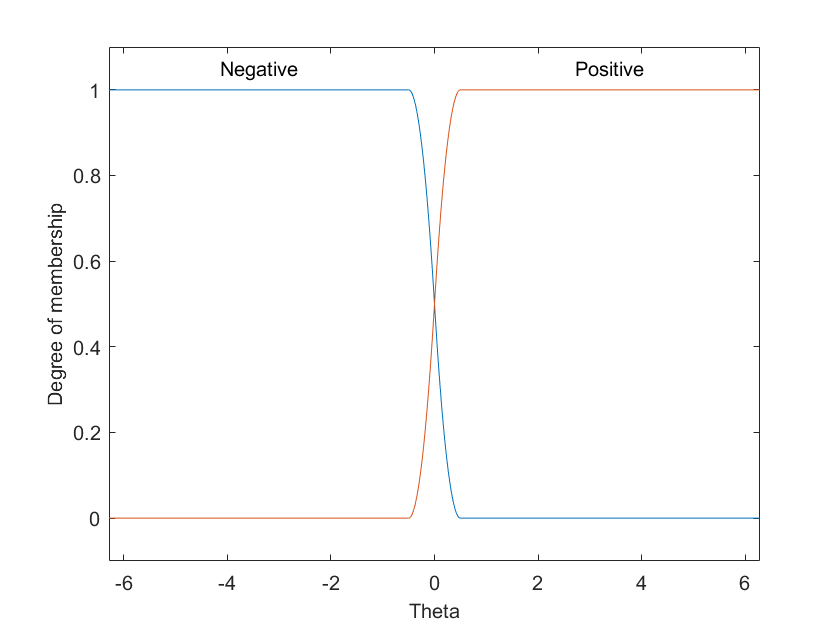

% Define input membership functions
FIS.Inputs(1).Name = 'Theta';       % Angle
FIS.Inputs(1).Range = [-2*pi, 2*pi];
FIS.Inputs(1).MembershipFunctions(1).Name = 'Negative';
FIS.Inputs(1).MembershipFunctions(1).Type = 'zmf';       % Z membership function
FIS.Inputs(1).MembershipFunctions(1).Parameters = [-0.5 0.5];
FIS.Inputs(1).MembershipFunctions(2).Name = 'Positive';
FIS.Inputs(1).MembershipFunctions(2).Type = 'smf';
FIS.Inputs(1).MembershipFunctions(2).Parameters = [-0.5 0.5];

FIS.Inputs(2).Name = 'Theta_dot';       % Angular velocity
FIS.Inputs(2).Range = [-10, 10];
FIS.Inputs(2).MembershipFunctions(1).Name = 'Negative';
FIS.Inputs(2).MembershipFunctions(1).Type = 'zmf';       % Z membership function
FIS.Inputs(2).MembershipFunctions(1).Parameters = [-5 5];
FIS.Inputs(2).MembershipFunctions(2).Name = 'Positive';
FIS.Inputs(2).MembershipFunctions(2).Type = 'smf';
FIS.Inputs(2).MembershipFunctions(2).Parameters = [-5 5];

FIS.Inputs(3).Name = 'Cart_pos';       % Position
FIS.Inputs(3).Range = [-10, 10];
FIS.Inputs(3).MembershipFunctions(1).Name = 'Negative';
FIS.Inputs(3).MembershipFunctions(1).Type = 'zmf';       % Z membership function
FIS.Inputs(3).MembershipFunctions(1).Parameters = [-.5 .5];     % Bound tightly
FIS.Inputs(3).MembershipFunctions(2).Name = 'Positive';
FIS.Inputs(3).MembershipFunctions(2).Type = 'smf';
FIS.Inputs(3).MembershipFunctions(2).Parameters = [-.5 .5];

FIS.Inputs(4).Name = 'Cart_vel';       % Velocity
FIS.Inputs(4).Range = [-5, 5];
FIS.Inputs(4).MembershipFunctions(1).Name = 'Negative';
FIS.Inputs(4).MembershipFunctions(1).Type = 'zmf';       % Z membership function
FIS.Inputs(4).MembershipFunctions(1).Parameters = [-1 1];    
FIS.Inputs(4).MembershipFunctions(2).Name = 'Positive';
FIS.Inputs(4).MembershipFunctions(2).Type = 'smf';
FIS.Inputs(4).MembershipFunctions(2).Parameters = [-1 1];

% Plot input membership functions
clf;
plotmf(FIS, 'input', 1, 1000);

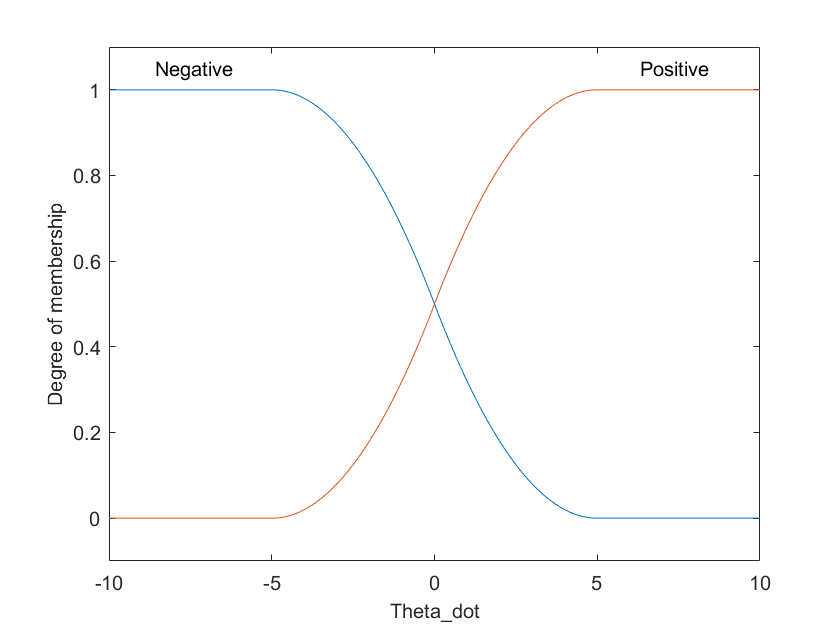

plotmf(FIS, 'input', 2, 1000);

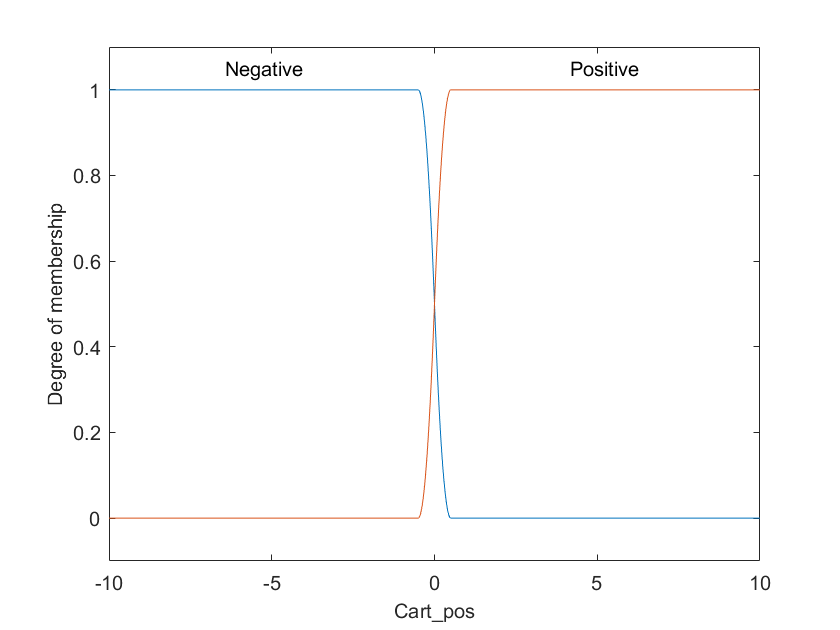

plotmf(FIS, 'input', 3, 1000);

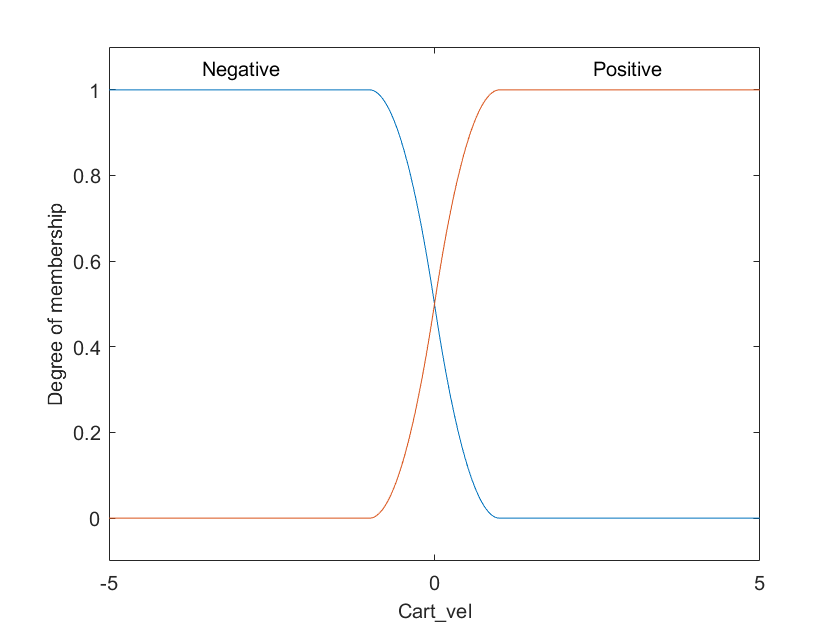

plotmf(FIS, 'input', 4, 1000);

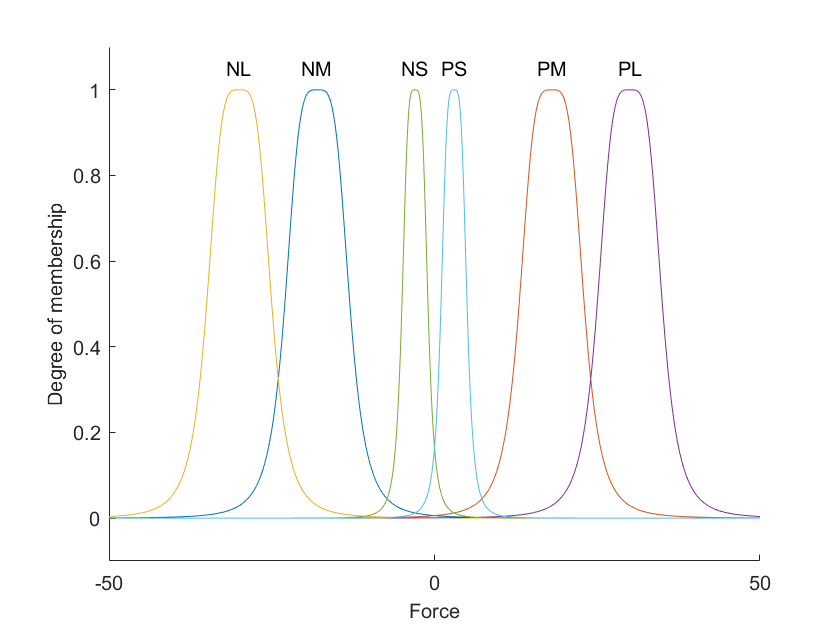

% Define output membership functions
FIS.Outputs(1).Name = 'Force';
FIS.Outputs(1).Range = [-50, 50];
FIS.Outputs(1).MembershipFunctions(1).Name = 'NM';      % Negative Medium
FIS.Outputs(1).MembershipFunctions(1).Type = 'gbellmf';  % Generalized Bell
FIS.Outputs(1).MembershipFunctions(1).Parameters = [5, 2, -18];
FIS.Outputs(1).MembershipFunctions(2).Name = 'PM';      % Positive Medium
FIS.Outputs(1).MembershipFunctions(2).Type = 'gbellmf';  % Generalized Bell
FIS.Outputs(1).MembershipFunctions(2).Parameters = [5, 2, 18];

FIS.Outputs(1).MembershipFunctions(3).Name = 'NL';      % Negative Large
FIS.Outputs(1).MembershipFunctions(3).Type = 'gbellmf';  % Generalized Bell
FIS.Outputs(1).MembershipFunctions(3).Parameters = [5, 2, -30];
FIS.Outputs(1).MembershipFunctions(4).Name = 'PL';      % Positive Large
FIS.Outputs(1).MembershipFunctions(4).Type = 'gbellmf';  % Generalized Bell
FIS.Outputs(1).MembershipFunctions(4).Parameters = [5, 2, 30];

FIS.Outputs(1).MembershipFunctions(5).Name = 'NS';      % Negative Small
FIS.Outputs(1).MembershipFunctions(5).Type = 'gbellmf';  % Generalized Bell
FIS.Outputs(1).MembershipFunctions(5).Parameters = [2, 2, -3];
FIS.Outputs(1).MembershipFunctions(6).Name = 'PS';      % Positive Small
FIS.Outputs(1).MembershipFunctions(6).Type = 'gbellmf';  % Generalized Bell
FIS.Outputs(1).MembershipFunctions(6).Parameters = [2, 2, 3];

% Plot output membership functions
clf; hold on;
plotmf(FIS, 'output', 1, 1000);

% Define rules
rules = [
    "If Theta is Negative then Force is NM";
    "If Theta is Positive then Force is PM";
    "If Theta_dot is Negative then Force is NL";
    "If Theta_dot is Positive then Force is PL";
    "If Cart_pos is Negative then Force is NS";
    "If Cart_pos is Positive then Force is PS";
    ];

% Add rules to FIS
FIS = addRule(FIS, rules);

## Tuning!

Tune membership functions based on outputs

% Load the Simulink model
model = 'discrete-fuzzy-control/genetic-algo/fuzzy_rocky_optimized'

model = 'discrete-fuzzy-control/genetic-algo/fuzzy_rocky_optimized'

load_system(model)

% plotfis(FIS);

% Run simulation programatically
% simOut = sim(model, ...
%              'SimulationMode', 'normal', ...
%              'SaveState','on', ...
%              'StateSaveName','xout', ...
%              'SaveOutput','on', ...
%              'OutputSaveName','yout', ...
%              'SaveFormat','dataset')

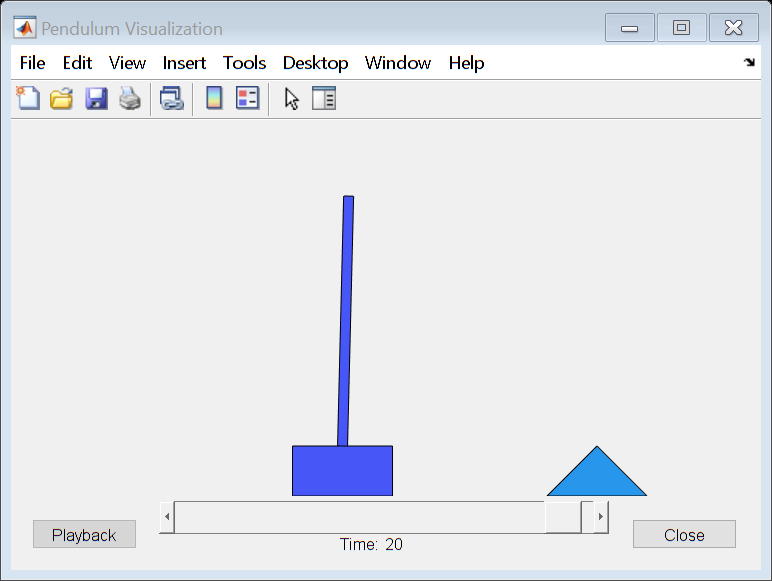

cost = 0.2231

ans = 0.2231

% Cost function!
minData = MinCostData;
costFnFis = FIS;
costFn(FIS, model, minData)

% Tune MFs
[inMF, outMF, rules] = getTunableSettings(FIS);
% Set options
opt = tunefisOptions;
opt.MethodOptions.MaxGenerations = 3;
opt.MethodOptions.PopulationSize = 10;
opt.Method = 'patternsearch'

opt =   tunefisOptions with properties:

                     Method: "patternsearch"
              MethodOptions: [1×1 optim.options.PatternsearchOptions]
           OptimizationType: "tuning"
                NumMaxRules: Inf
    IgnoreInvalidParameters: 1
             DistanceMetric: "rmse"
                UseParallel: 0
                 KFoldValue: 0
        ValidationTolerance: 0.1000
       ValidationWindowSize: 5
                    Display: "all"


opt.MethodOptions.MaxIterations = 10;

% Tune the input membership functions using a genetic algorithm
% Uses costFn.m
fisMFTuned = tunefis(FIS, [inMF; outMF], @(FIS)costFn(FIS, model, minData), opt)

cost = 0.2368



Iter     Func-count       f(x)      MeshSize     Method
    0           1       0.236805             1      


cost = 1.0340e+03

cost = 652.9797

cost = 0.4100

cost = 0.4130

cost = 0.3477

cost = 0.2712

cost = 0.2368

cost = 0.2368

cost = 0.2368

cost = 0.2368

cost = 379.9995

cost = 52.8983

cost = 1.0428e+03

cost = 671.2543

cost = 0.3772

cost = 0.4151

cost = 0.5008

cost = 0.4567

cost = 0.2368

cost = 0.2368

cost = 0.2368

cost = 0.2368

cost = 824.6931

cost = 53.2182

    1          25       0.236805           0.5     Refine Mesh


cost = 590.0370

cost = 404.9192

cost = 757.8419

cost = 601.4388

cost = 641.0432

cost = 9.2410

cost = 578.0104

cost = 13.7453

cost = 0.2791

cost = 0.2988

cost = 0.2162

    2          36       0.216214             1     Successful Poll


cost = 861.3479

cost = 994.2545

cost = 0.4793

cost = 0.5224

cost = 0.3946

cost = 0.2162

cost = 0.2162

cost = 0.2162

cost = 0.2162

cost = 1.0526e+03

cost = 51.8197

cost = 1.0760e+03

cost = 703.8320

cost = 0.2861

cost = 0.3707

cost = 0.3509

cost = 0.3349

cost = 0.2162

cost = 0.2162

cost = 0.2162

cost = 0.2162

cost = 378.1358

cost = 54.5425

    3          59       0.216214           0.5     Refine Mesh


cost = 742.5301

cost = 425.4260

cost = 591.0046

cost = 596.5843

cost = 581.9858

cost = 9.3098

cost = 650.0538

cost = 14.1075

cost = 0.3422

cost = 0.3573

cost = 0.3477

cost = 0.3418

cost = 0.2162

cost = 0.2162

cost = 0.2162

cost = 0.2162

cost = 12.6279

cost = 0.2178

cost = 593.3604

cost = 13.1781

cost = 0.5108

cost = 8.6559

cost = 728.5735

cost = 4.6133

cost = 535.4671

cost = 746.0483

cost = 4.1363

cost = 390.1863

cost = 0.2160

    4          88       0.215966             1     Successful Poll


cost = 884.6850

cost = 672.8852

cost = 0.4666

cost = 0.4847

cost = 0.3894

cost = 0.2160

cost = 0.2160

cost = 0.2160

cost = 0.2160

cost = 853.7432

cost = 52.5106

cost = 900.0819

cost = 689.0454

cost = 0.3121

cost = 0.3752

cost = 0.3701

cost = 0.3524

cost = 0.2160

cost = 0.2160

cost = 0.2160

cost = 0.2160

cost = 359.3838

cost = 51.9986

cost = 223.4117

    5         112       0.215966           0.5     Refine Mesh


cost = 725.5041

cost = 412.1229

cost = 364.6492

cost = 773.7549

cost = 525.7371

cost = 9.4659

cost = 768.5063

cost = 14.0994

cost = 0.3369

cost = 0.3374

cost = 0.3458

cost = 0.3401

cost = 0.2160

cost = 0.2160

cost = 0.2160

cost = 0.2160

cost = 12.6282

cost = 0.3195

cost = 653.4965

cost = 13.2096

cost = 0.5059

cost = 8.6229

cost = 728.5735

cost = 4.6395

cost = 585.4313

cost = 593.6043

cost = 4.1798

cost = 4.9662

cost = 6.9737

cost = 91.7612

cost = 0.2175

cost = 0.3083

% Save the genetic algorithm tuning so we don't have to run it again
save("fisMFTuned.mat", "fisMFTuned")